# **课程设计：利用 PDE 工具箱和天线工具箱设计铁罐天线**

**        铁罐天线是集单极子天线与微波波导为一体的背射天线。铁罐天线主要利用茶叶罐、咖啡罐等金属容器作为波导和反射器，单极天线作为激励。因其取材方便、制作简单、贴近工程实际，又与课堂知识紧密结合的特点，使得铁罐天线的设计、仿真、制作、测量项目受到学生的广泛好评，对学生更好的理解电磁波的辐射、波导、天线等都具有很好的帮助。MATLAB 中的 PDE 工具箱可以方便地**[**分析圆形波导的本征模**](matlab:open('..\..\2．MATLAB 功能程序源代码\E 第五章 时变电磁场\E5_Solving_the_Wave_Equation_with_the_PDE_Toolbox.mlx'))**，而天线工具箱能够高效计算方向图等天线参数，从而为铁罐天线的可视化设计提供了很大的方便。通过利用 PDE工具箱和天线工具箱设计铁罐天线，让学生体会通过编程来执行算法并生成可视化结果的过程，加深对求解电磁场电磁波各种数值算法如有限元法、矩量法等的理解。**

## **一、定义参数**

**        设计频点为2.45GHz，此时真空波长：**

c=3e8;%光速
f=2.45e9;
lambda=c/f;
fprintf('真空波长为%dm',lambda);

真空波长为1.224490e-01m

**        要求单模传输，因此真空波长应当小于TE11模的截止波长（3.41R），大于TM01模截止波长（2.62R），R为铁罐半径**

Rmax=lambda/2.62;
Rmin=lambda/3.41;
fprintf('单模传输的半径选择范围为[%dm,%dm]',Rmin,Rmax);

单模传输的半径选择范围为[3.590879e-02m,4.673625e-02m]

R =0.044

R = 0.0440

**        波导波长：**


$$\frac{1}{\lambda_g^2 }=\frac{1}{\lambda^2 }-\frac{1}{\lambda_c^2 }$$


lambdac = 3.41*R;
fprintf('截止波长lambdac=%dm\n',lambdac);

截止波长lambdac=1.500400e-01m


lambdag = sqrt(1/(1/lambda^2-1/lambdac^2));
fprintf('波导波长lambdag=%dm\n',lambdag);

波导波长lambdag=2.118868e-01m


**        由于馈电位置为1/4波导波长时，天线的阻抗匹配和辐射效率往往是最佳的。为了满足馈电位置的选择，铁罐长度H的最小值也为1/4波导波长**

Hmin = lambdag/4;
fprintf('铁罐长度最小值Hmin=%dm\n',Hmin);

铁罐长度最小值Hmin=5.297170e-02m


**注意：当铁罐半径R过小时，铁罐长度H难以满足1/4波导波长的要求。如当铁罐半径为3.6cm时，铁罐长度最小值约为43cm。**

H =0.1839716964866927

H = 0.1840

## **二、使用PDE工具箱计算圆波导的主模（基模）**

              Basis= 10,  Time=   0.00,  New conv eig=  1
              Basis= 18,  Time=   0.02,  New conv eig=  3
              Basis= 26,  Time=   0.02,  New conv eig=  6
              Basis= 34,  Time=   0.02,  New conv eig=  8
End of sweep: Basis= 34,  Time=   0.02,  New conv eig=  8
              Basis= 18,  Time=   0.06,  New conv eig=  0
End of sweep: Basis= 18,  Time=   0.06,  New conv eig=  0


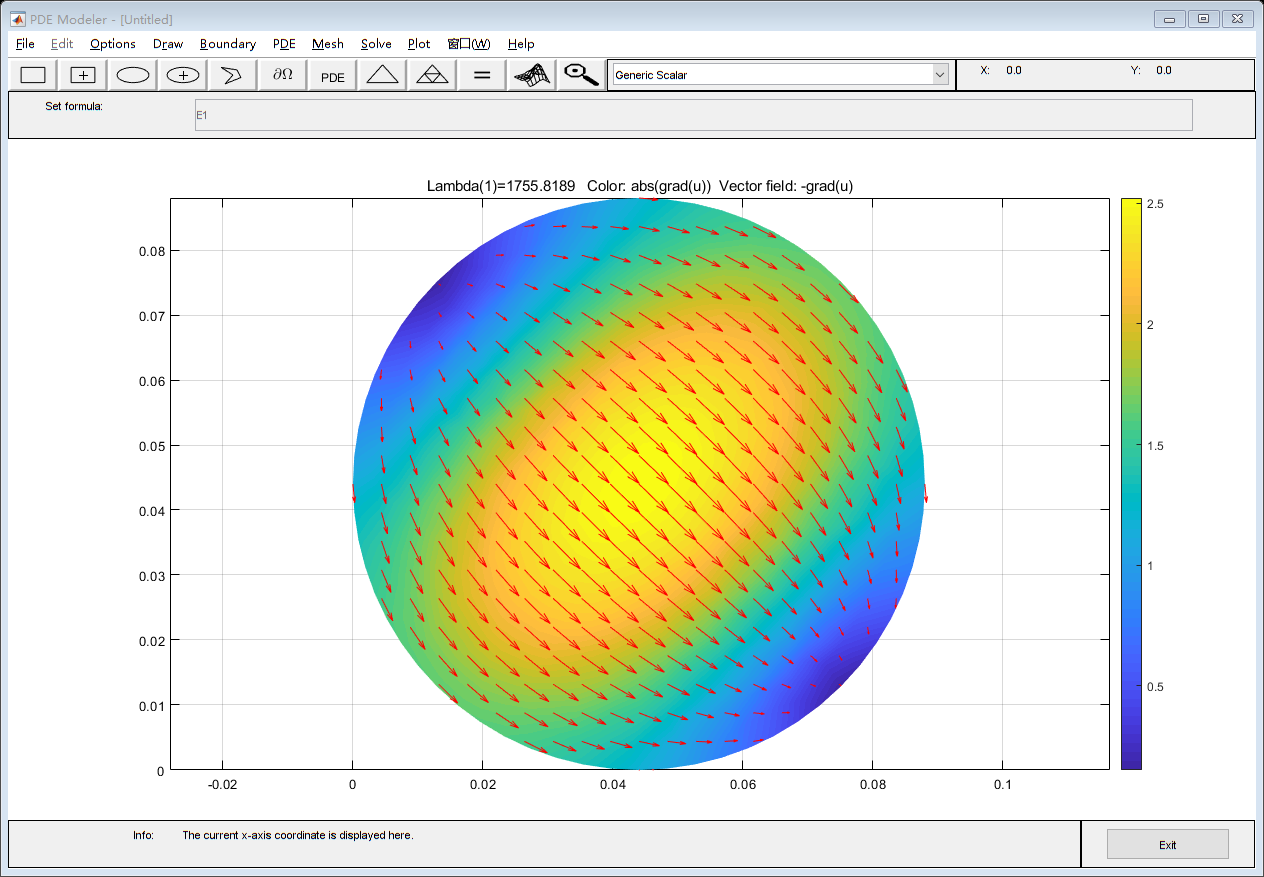

waveguide(R);

**        由于：**


$$\lambda_c =\frac{2\pi }{k_c }$$


**        截止波长已知（3.41R），可求得**$k_c$**：**

kc = 2*pi/lambdac

kc = 41.8767

**        TE11(H11)模为圆波导的基模，此时：**


$$\lambda \left(1\right)=k_c^2$$


lambda1 = kc ^ 2

lambda1 = 1.7537e+03

**可以看出PDE工具箱计算圆波导结果是正确的。**

## **三、使用天线工具箱设计铁罐天线**

**        首先调用waveguideCircular设计模板，该设计模板对应圆波导天线。**

c1 = waveguideCircular;
c1.Radius=R;
c1.Height=H;

**        设置馈电位置(1/4波导波长处）、高度、宽度：**

c1.FeedOffset=lambdag/4;
c1.FeedHeight=lambda/4;
c1.FeedWidth = 0.003;

**        查看铁罐天线的全部参数：**

c1

c1 =   waveguideCircular - 属性:

        Radius: 0.0440
        Height: 0.1840
    FeedHeight: 0.0306
     FeedWidth: 0.0030
    FeedOffset: 0.0530
     Conductor: [1×1 metal]
          Tilt: 0
      TiltAxis: [1 0 0]
          Load: [1×1 lumpedElement]


**        网格划分：**

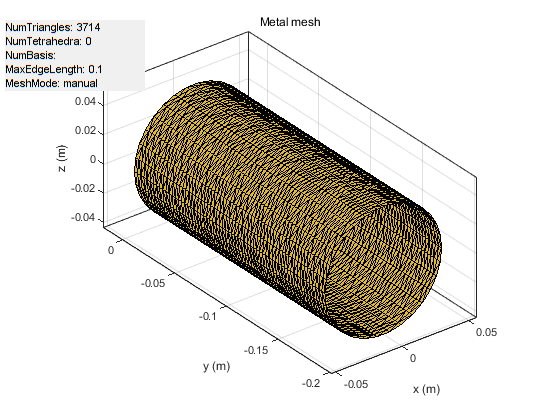

figure
mesh(c1,'MaxEdgeLength',.1);

## **四、扫参优化**

**        对馈电位置进行扫参优化，将谐振点移动至2.45GHz。**

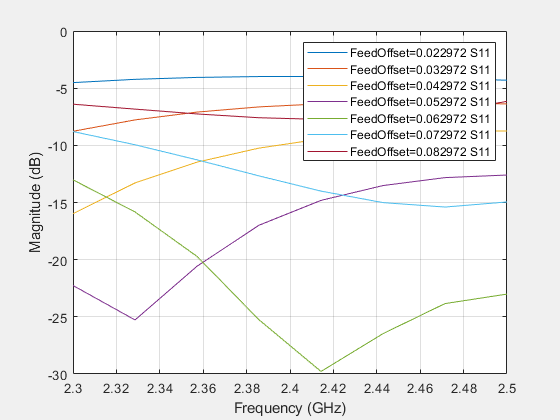

legE=[];
S11_value=0;
figure
set(gcf,'Visible','on');   	    %强制图片弹出显示
for FeedOffset = lambdag/4-30e-3:10e-3:lambdag/4+30e-3
    c1.FeedOffset = FeedOffset;
    S = sparameters(c1, f); 
    S11_value_op = 20 * log10(abs(S.Parameters(1, 1)));
    if S11_value > S11_value_op
        S11_value = S11_value_op;
        BestFeedOffset=FeedOffset;
    end
    S = sparameters(c1,linspace(2.3e9,2.5e9,8));
    rfplot(S);
    legE = [legE , strcat('FeedOffset=', string(FeedOffset), ' S11')];
    hold on
end
legend(legE);

**        将馈电位置设置为最优的馈电位置：**

fprintf('最佳馈电位置BestFeedOffset=%dm\n',BestFeedOffset);

最佳馈电位置BestFeedOffset=6.297170e-02m


c1.FeedOffset = BestFeedOffset;

## **五、结果仿真**

**        绘制2.45GHz时的方向图：**

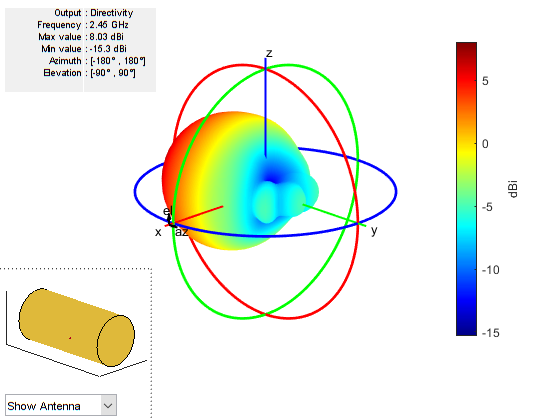

figure
pattern(c1,f)

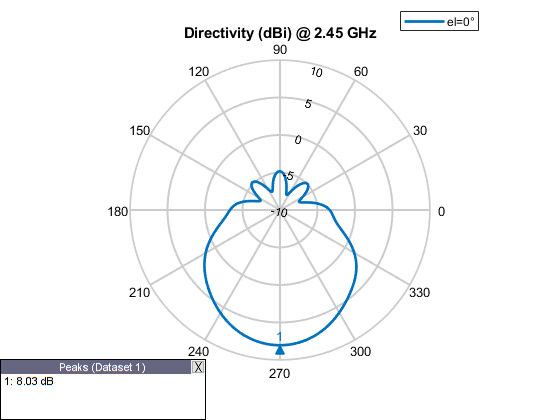

figure
patternAzimuth(c1, f)

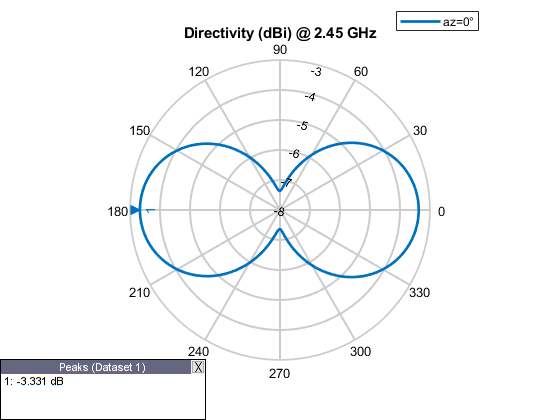

figure
patternElevation(c1, f)

**        铁罐天线的阻抗曲线**

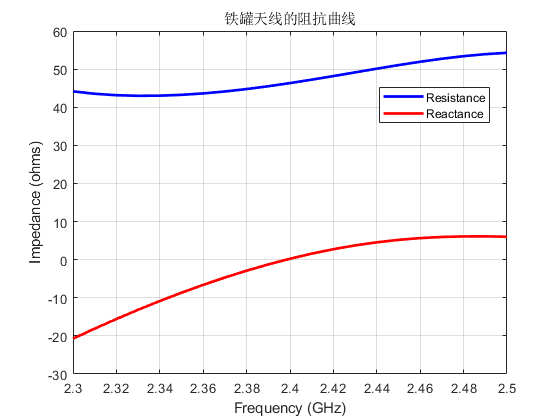

figure
impedance(c1,linspace(2.3e9,2.5e9,21));
title('铁罐天线的阻抗曲线');

**        铁罐天线的反射系数**

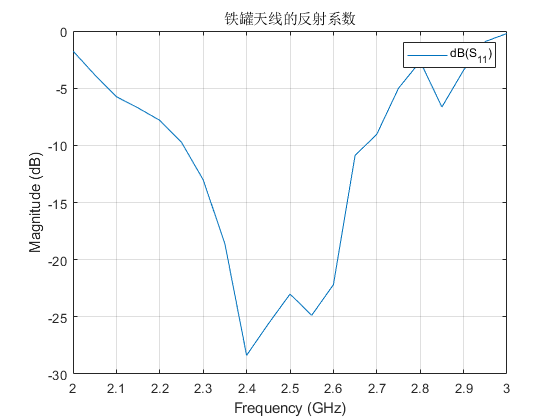

S=sparameters(c1,linspace(2e9,3e9,21));
figure
rfplot(S);
title('铁罐天线的反射系数');
set(gcf,'Visible','on');   	    %强制图片弹出显示

function waveguide(R)
    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',1);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.6434567901234569 1 16.666666666666671]);
    set(ax,'XLimMode','auto');
    set(ax,'YLim',[0 R*2]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    pdetool('gridon','on');
    
    % Geometry description:
    pdeellip(R,R,R,R,...
    0,'E1');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','E1')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'neu',...
    1,...
    '0',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(4,...
    '1.0',...
    '0.0',...
    '10.0',...
    '1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[1 10000]')
    setappdata(pde_fig,'currparam',...
    ['1.0 ';...
    '0.0 ';...
    '10.0';...
    '1.0 '])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','1608','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[2 1 1 1 1 1 10 1 0 0 0 1 1 0 0 1 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
    
end

## **参考文献：**

**        [1] https://ww2.mathworks.cn/help/antenna/ref/waveguidecircular.html**

**        [2] Jadhav R P, Dongre V J, Heddallikar A. Design of X-band conical horn antenna using coaxial feed and improved design technique for bandwidth enhancement[C]//2017 International Conference on Computing, Communication, Control and Automation (ICCUBEA). IEEE, 2017: 1-6.**